# Bayesian Statistics

clear; clc;
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Bayesian Statistics')

## Likelihood of W for a single toss

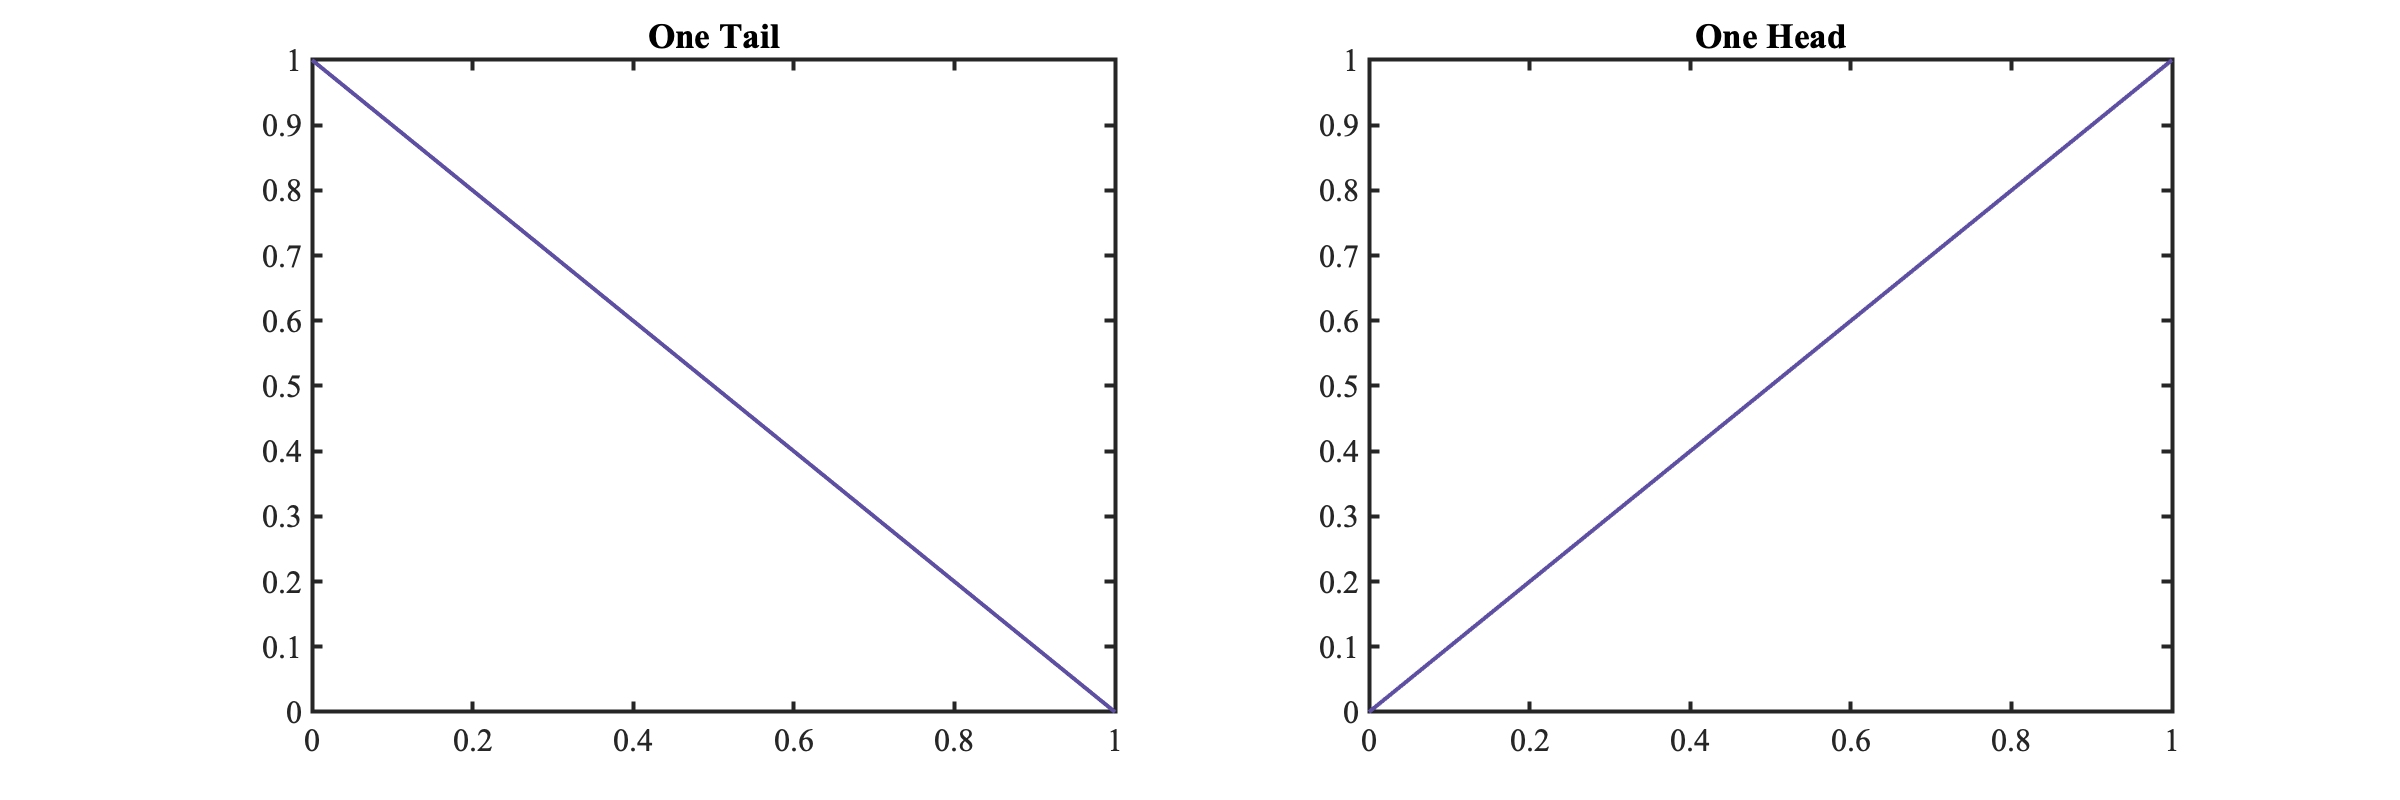

binomlike = @(n, y, w) (factorial(n) / (factorial(y) * factorial(n-y))) .* w.^y .* (1 - w).^(n-y);
w = linspace(0, 1, 500);

figure('position', [300 300 1200 400]);
subplot(1,2,1);
plot(w, binomlike(1, 0, w));
title('One Tail');

subplot(1,2,2);
plot(w, binomlike(1, 1, w));
title('One Head');

## Likelihood of P for 3 tosses

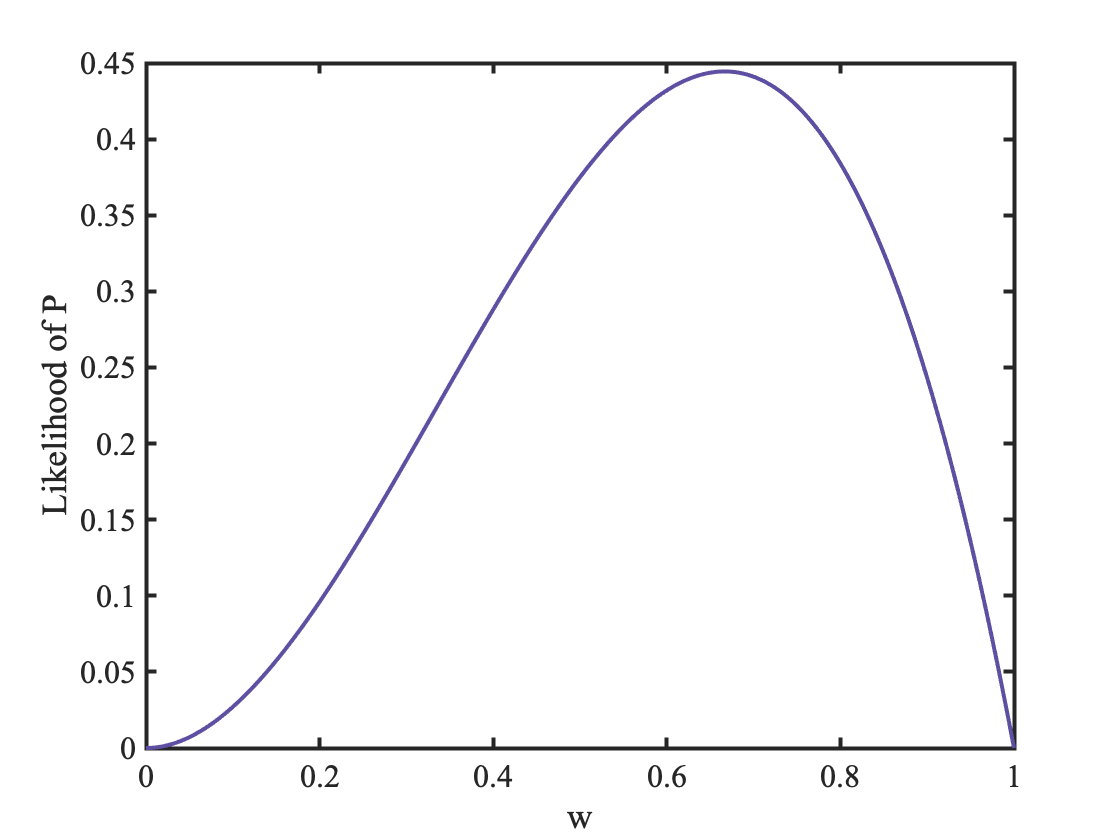

figure()
plot(w, binomlike(3, 2, w))
xlabel('w')
ylabel('Likelihood of P')

## Beta Distribution Conjugate Prior

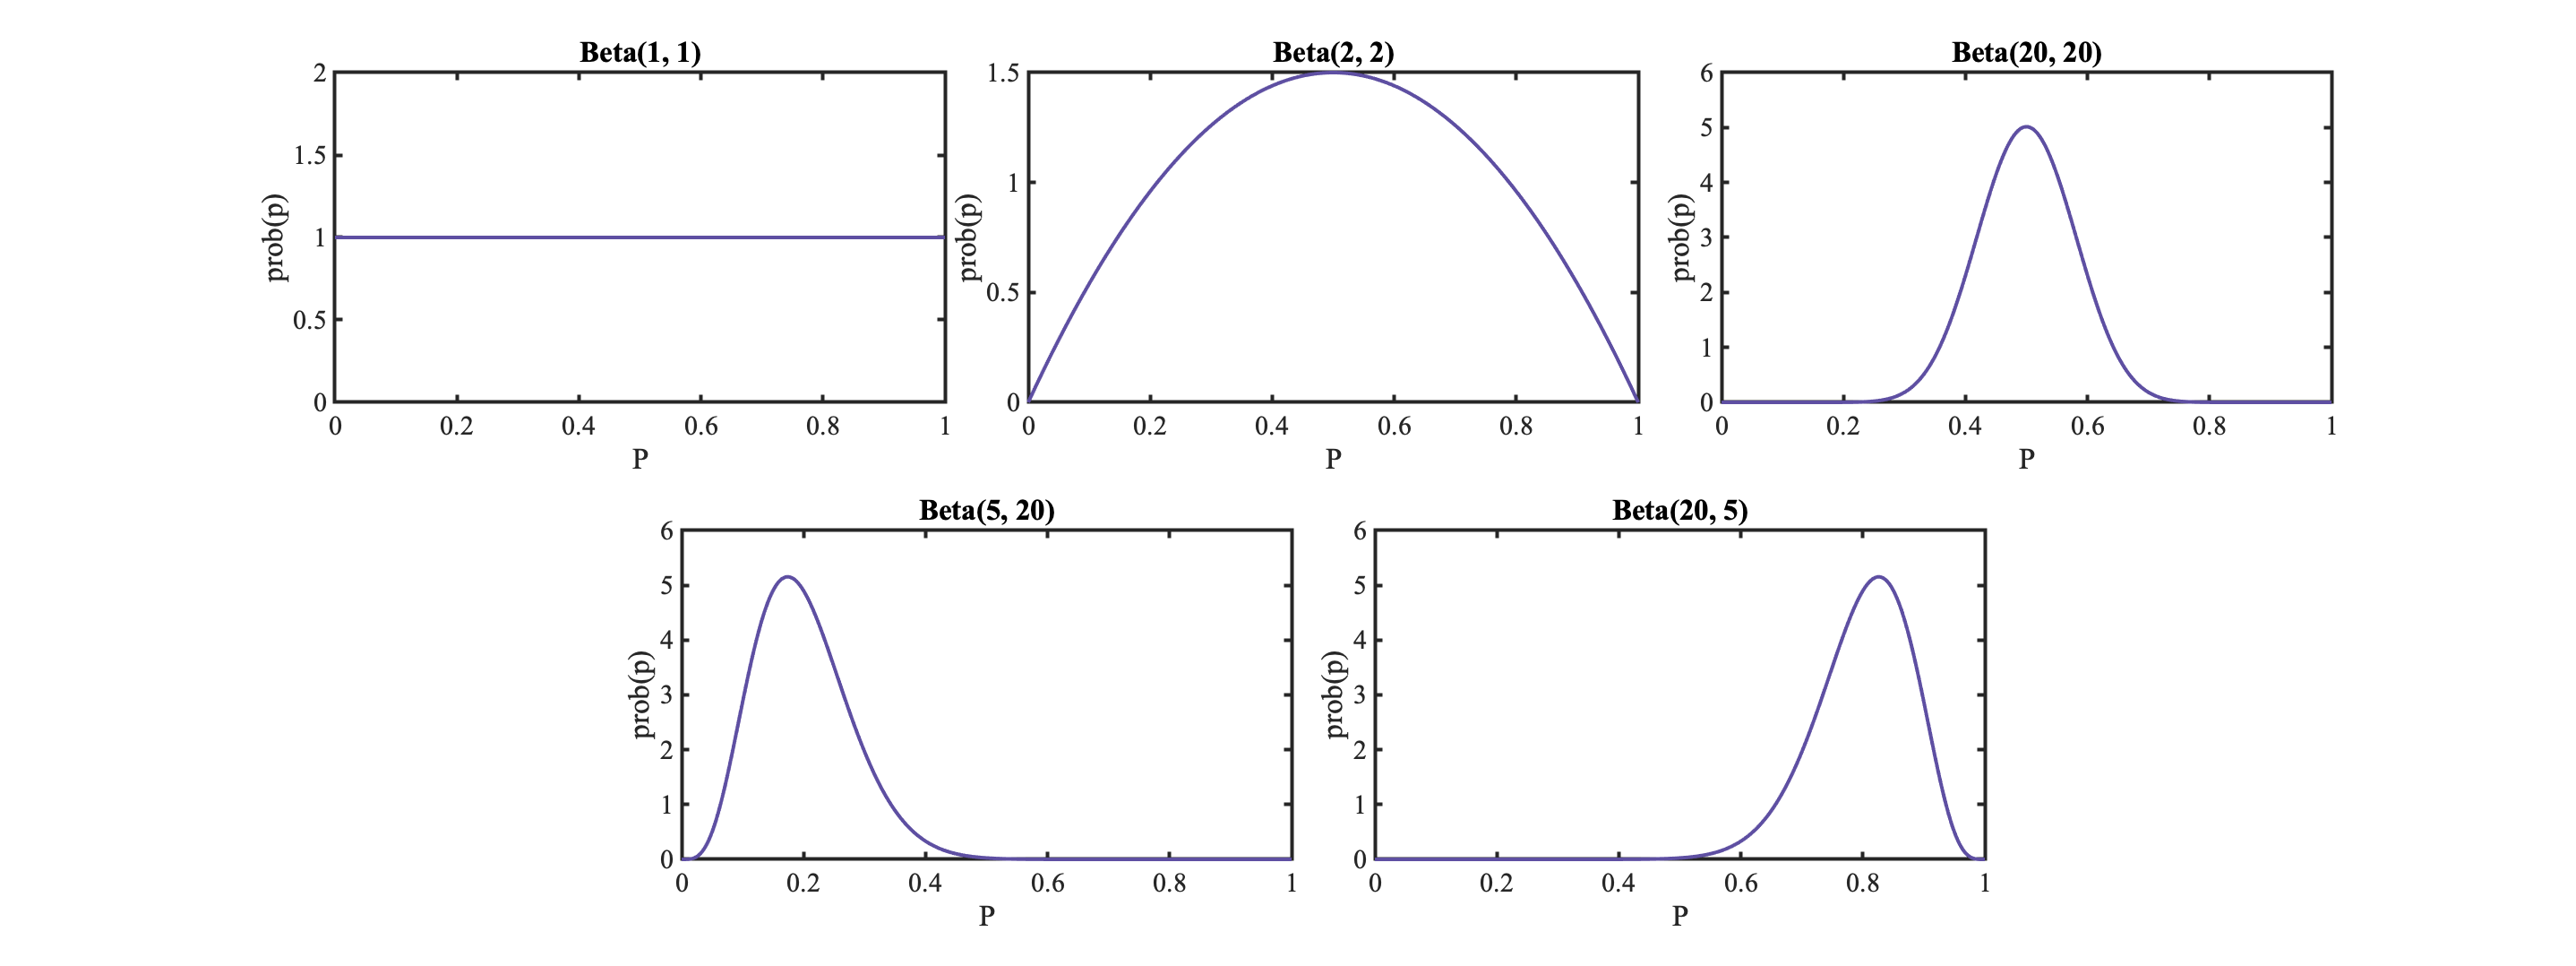

alpha = [1,2,20,5,20];
beta = [1,2,20,20,5];
startSP = [1 3 5 8 10];
endSP = [2 4 6 9 11]; 
figure('position', [300 300 1600 600]);
for i = 1:length(alpha)
    subplot(2, 6, [startSP(i) endSP(i)]); 
    plot(w, betapdf(w, alpha(i), beta(i)));
    xlabel('P');
    ylabel('prob(p)')
    title(sprintf('Beta(%d, %d)', alpha(i), beta(i)))
end

## Toss One - Heads

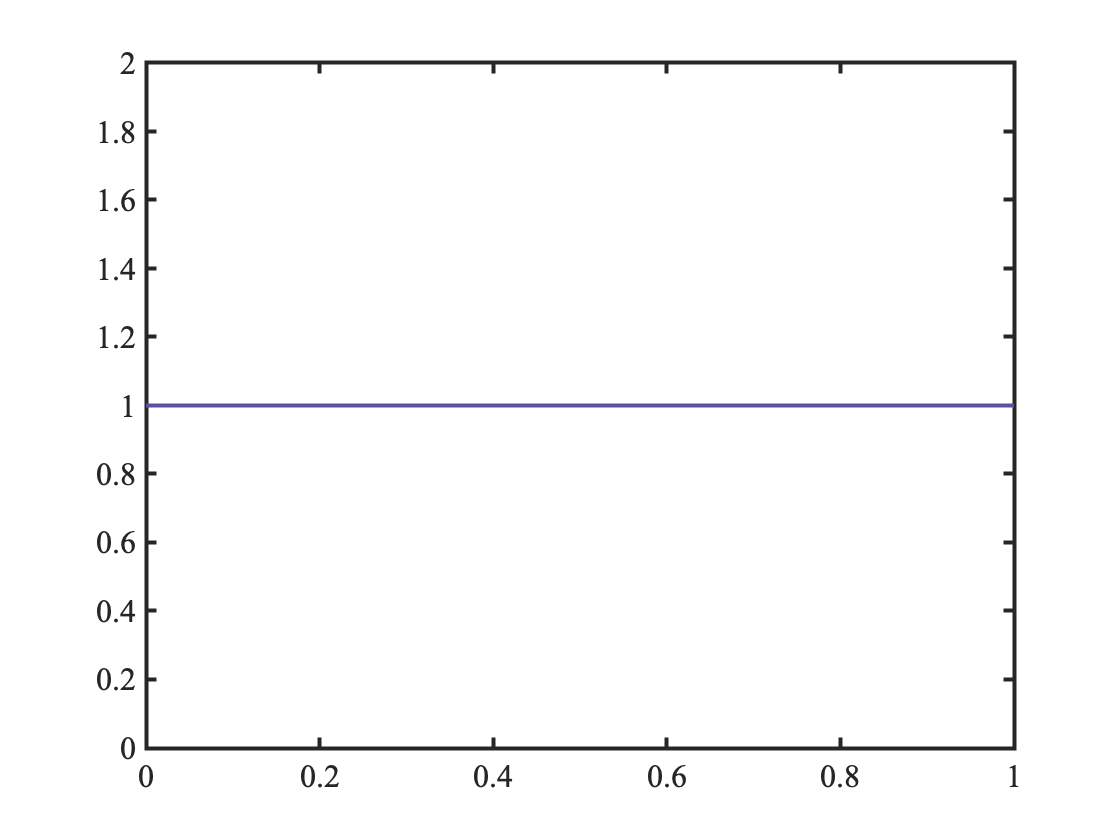

prior = betapdf(w, 1, 1);
likelihood = binomlike(1, 1, w);
posterior = prior .* likelihood;
posterior = posterior / sum(posterior); 

figure();
plot(w, prior);

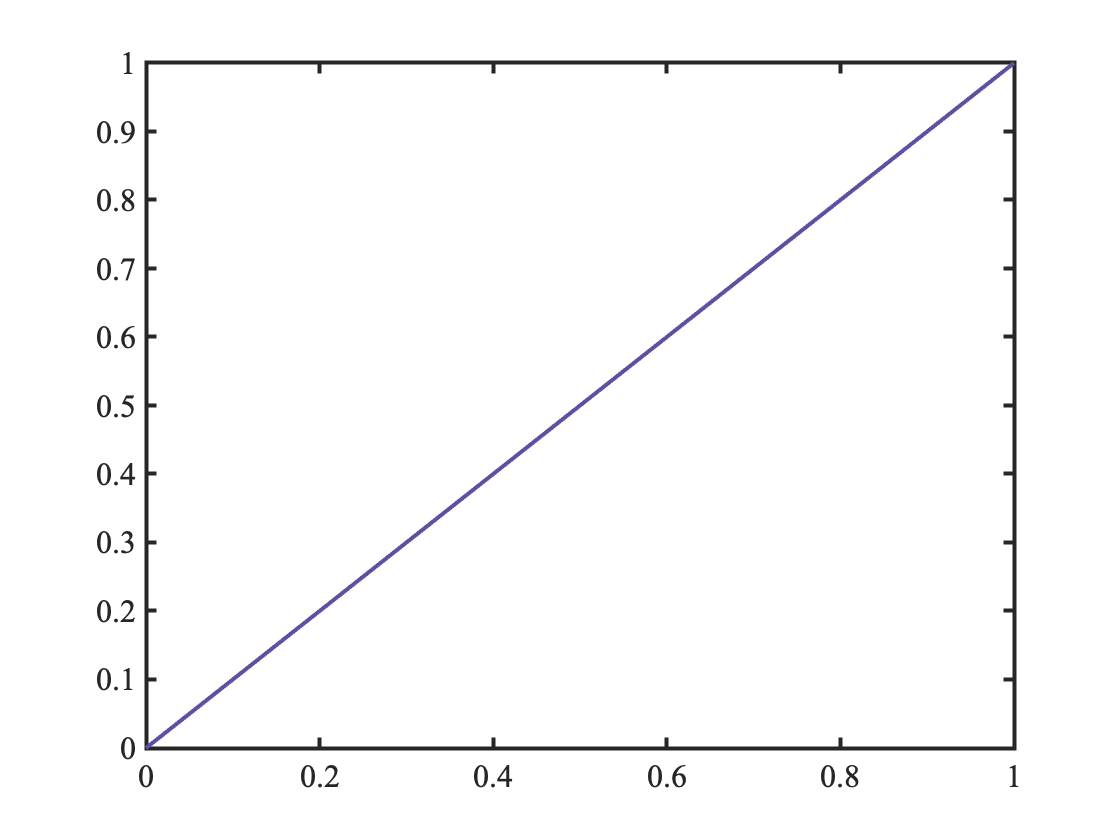


figure();
plot(w, likelihood);

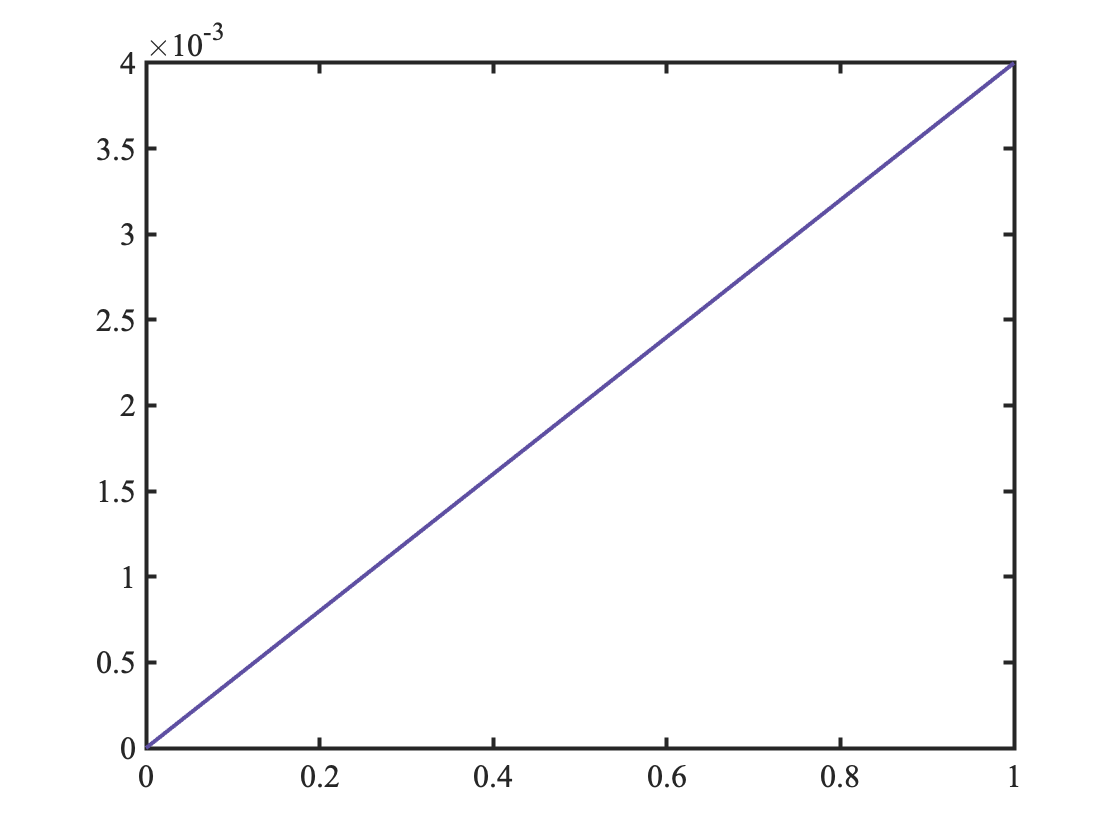


figure();
plot(w, posterior);

## Toss Two - Tails

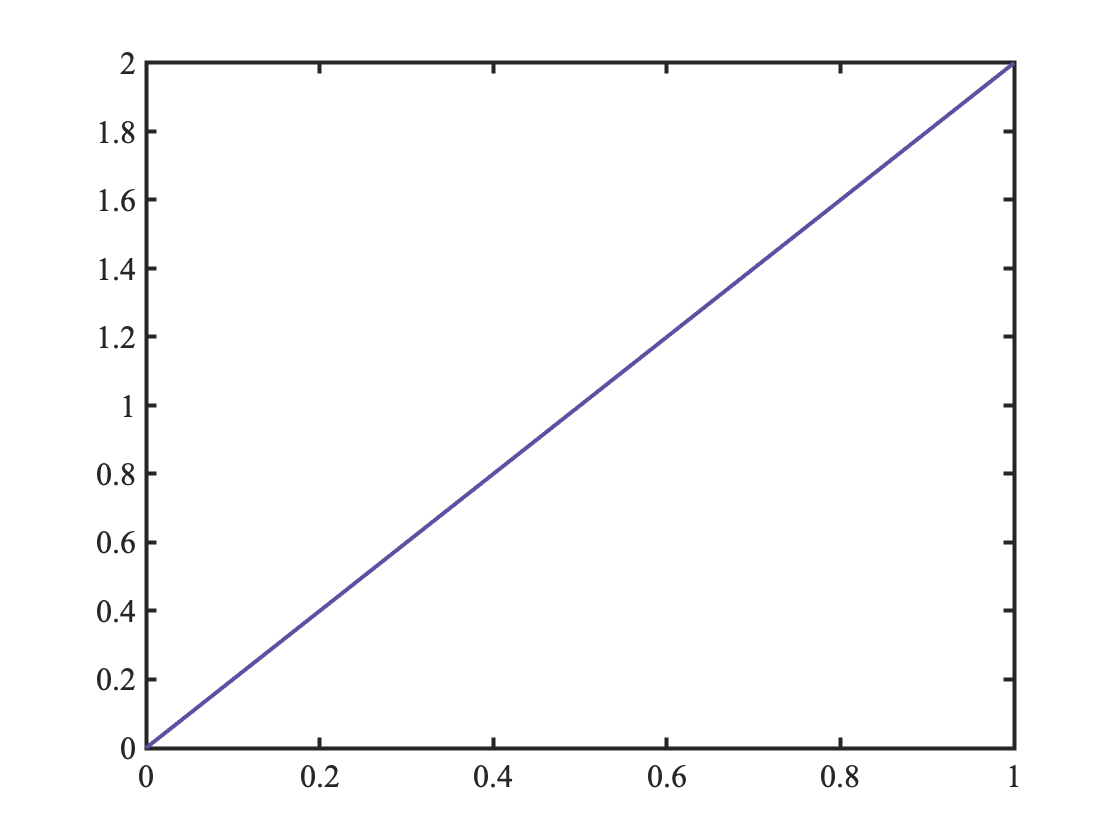

prior = betapdf(w, 2, 1);
likelihood = binomlike(1, 0, w);
posterior = prior .* likelihood;
posterior = posterior / sum(posterior); 

figure();
plot(w, prior);

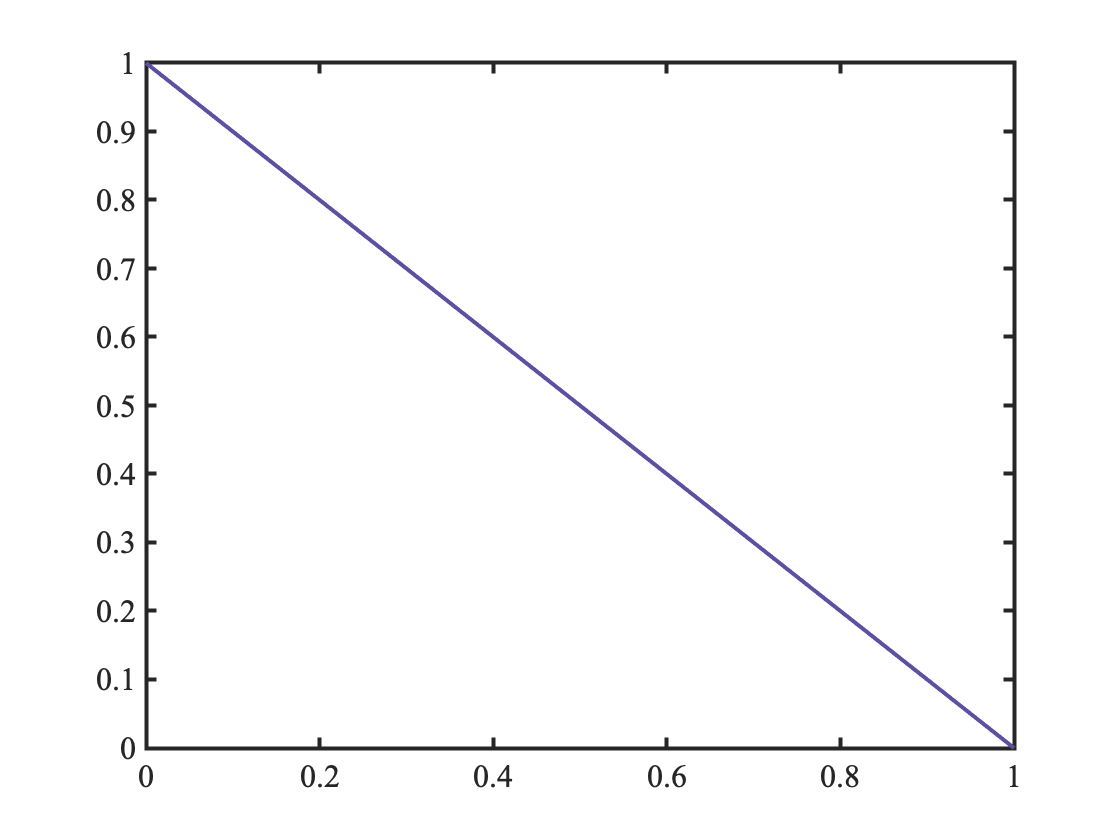


figure();
plot(w, likelihood);

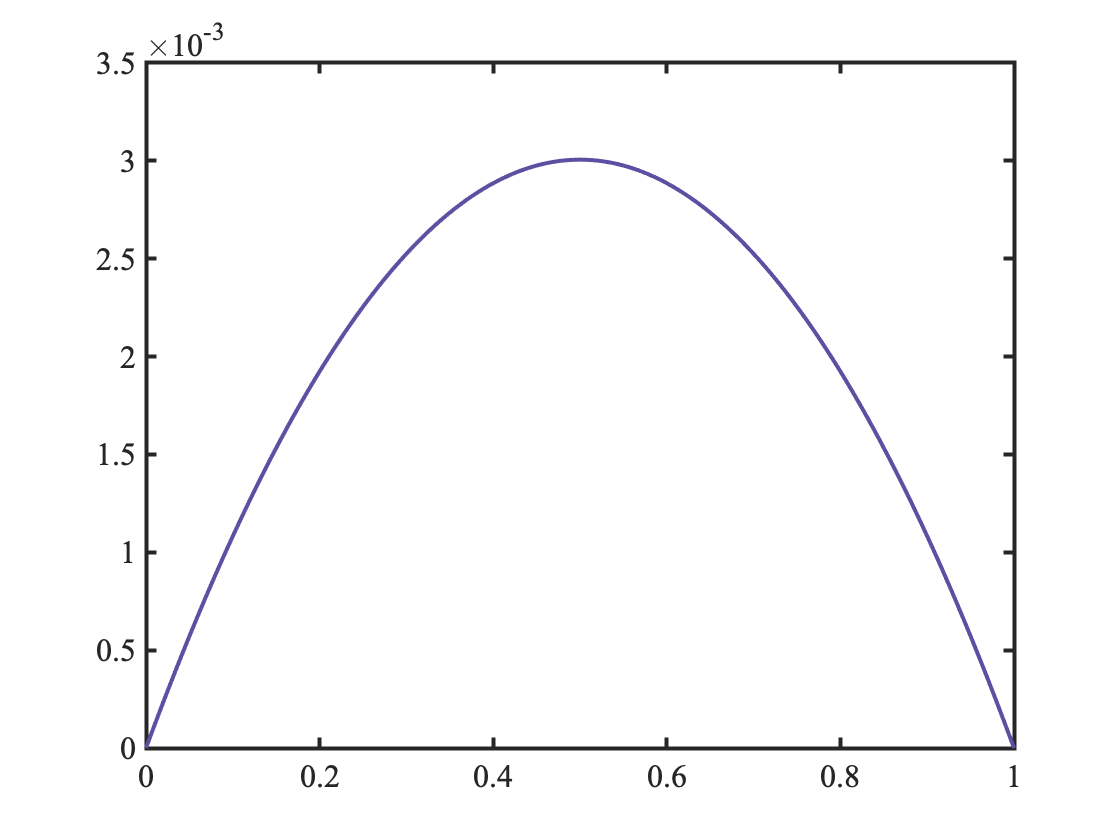


figure();
plot(w, posterior);

## Toss Three - Heads

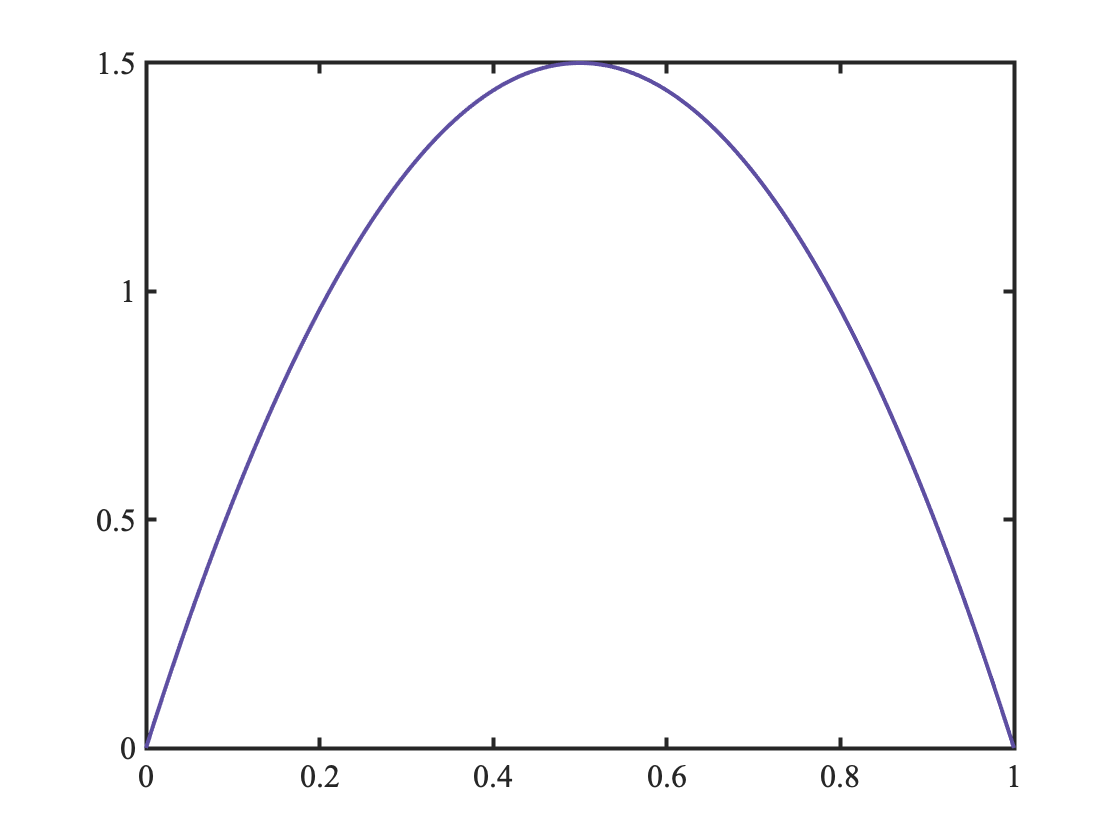

prior = betapdf(w, 2, 2);
likelihood = binomlike(1, 1, w);
posterior = prior .* likelihood;
posterior = posterior / sum(posterior); 

figure();
plot(w, prior);


figure();
plot(w, likelihood);

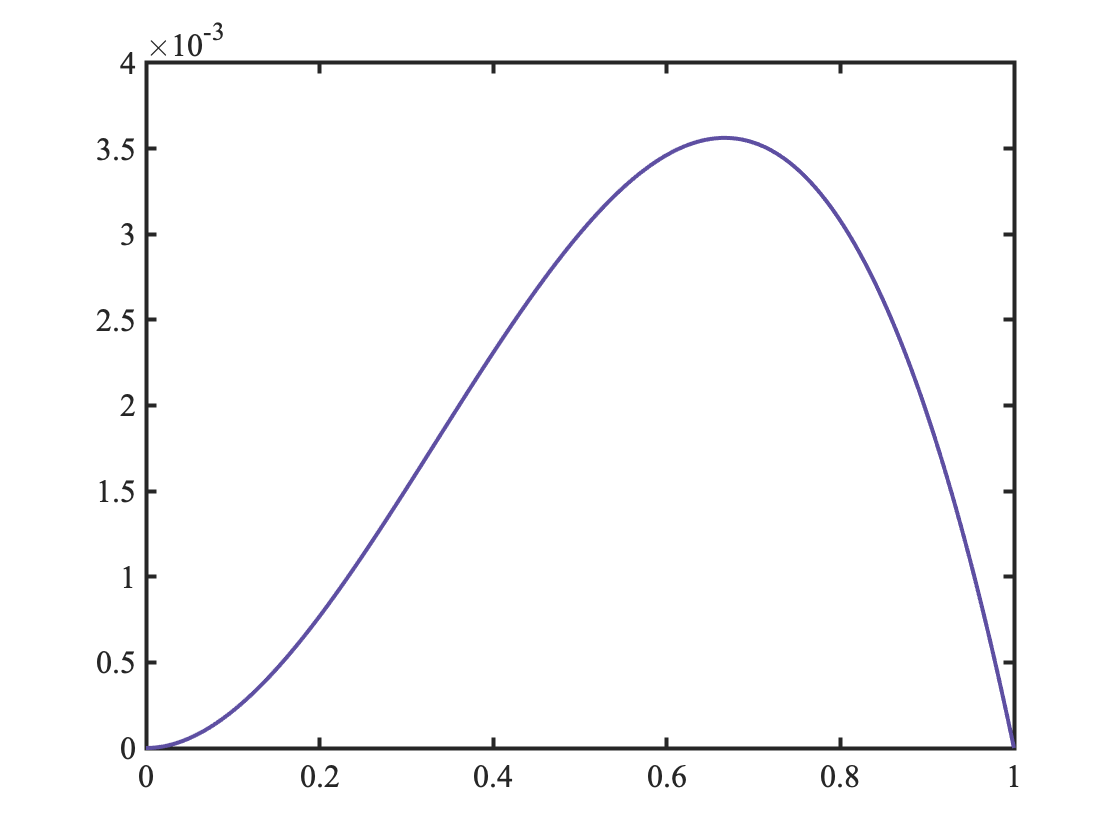


figure();
plot(w, posterior);

## Effect of Prior

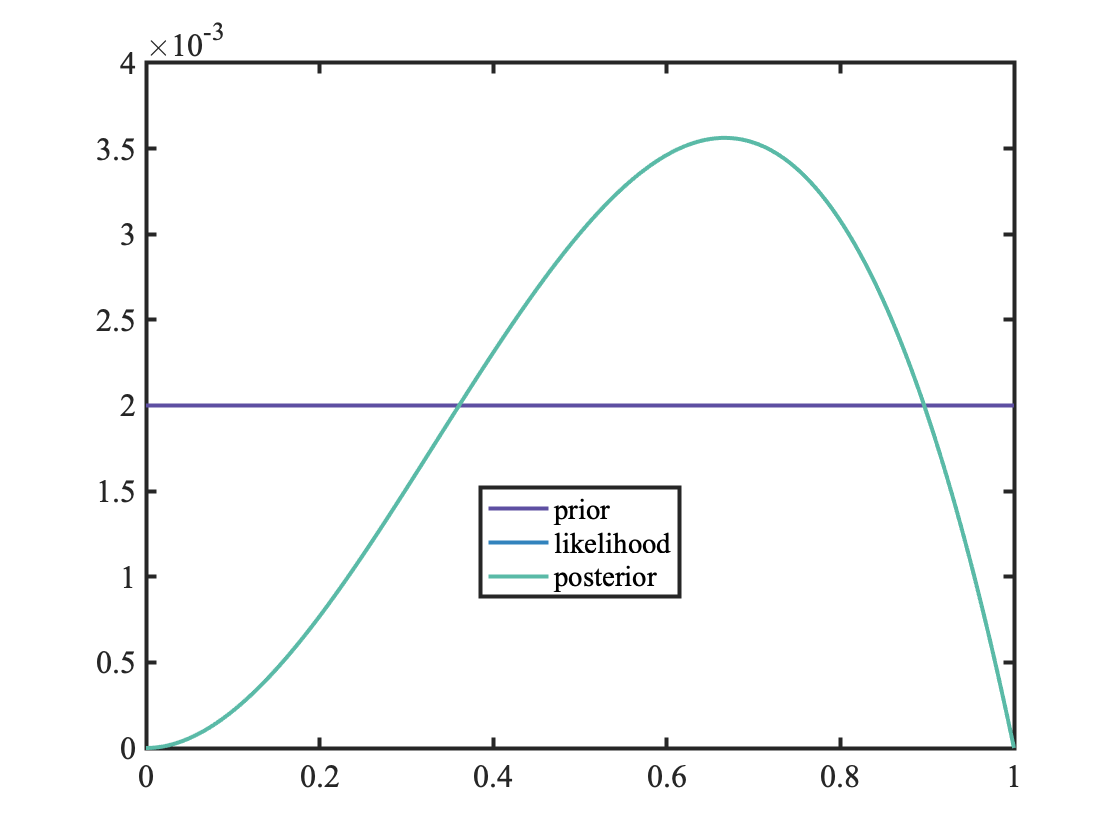

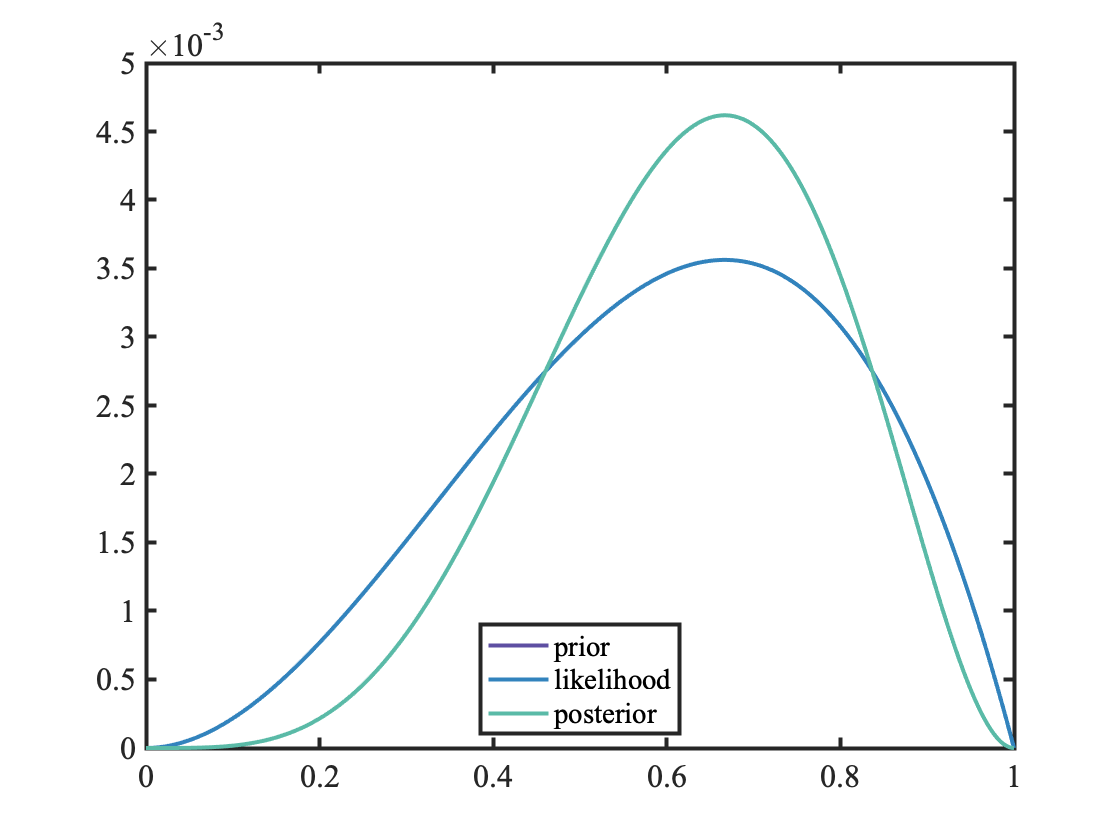

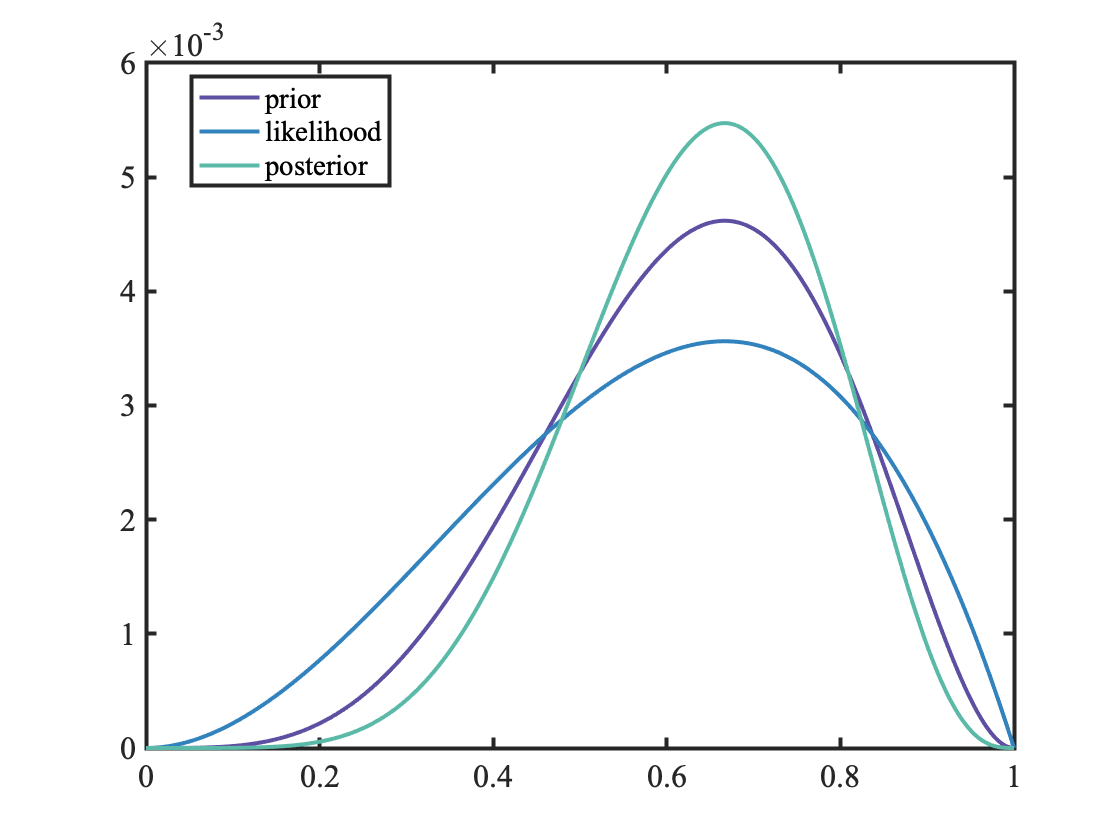

prior = pdf('uniform', w, 0, 1) * 0.002;
for t = 1:3
    likelihood = binomlike(3, 2, w);
    likelihood = likelihood / sum(likelihood);
    posterior = prior .* likelihood;
    posterior = posterior / sum(posterior);
    
    figure()
    plot(w, prior, 'displayname', 'prior');
    hold on; 
    plot(w, likelihood, 'displayname', 'likelihood');
    plot(w, posterior, 'displayname', 'posterior');
    legend('location', "best");

    % update 
    prior = posterior;
end

## Analytically Describing the Posterior

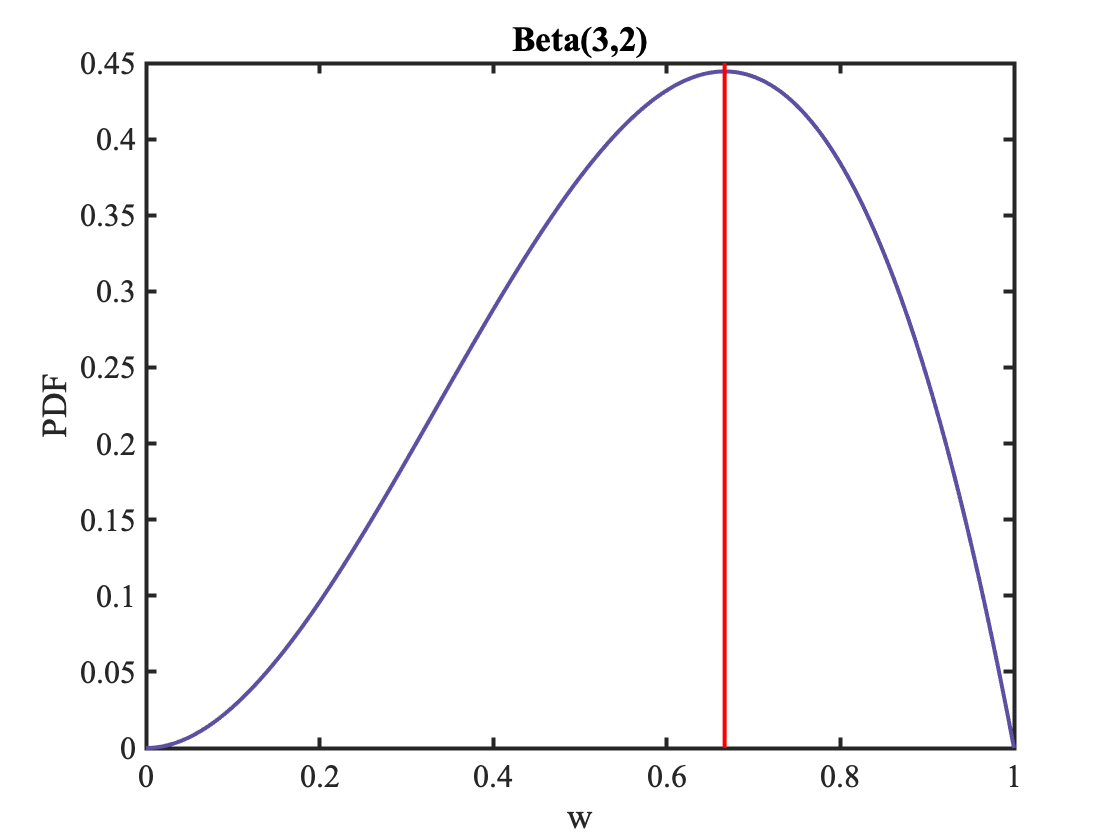

k = 2;
n = 3;
likelihood = binomlike(n, k, w);

MLE = k/n; 

figure(); 
plot(w, likelihood);
hold on 
plot([MLE MLE], get(gca, 'ylim'), 'r')
xlabel('w')
ylabel('PDF')
title('Beta(3,2)')

## Grid Approximation

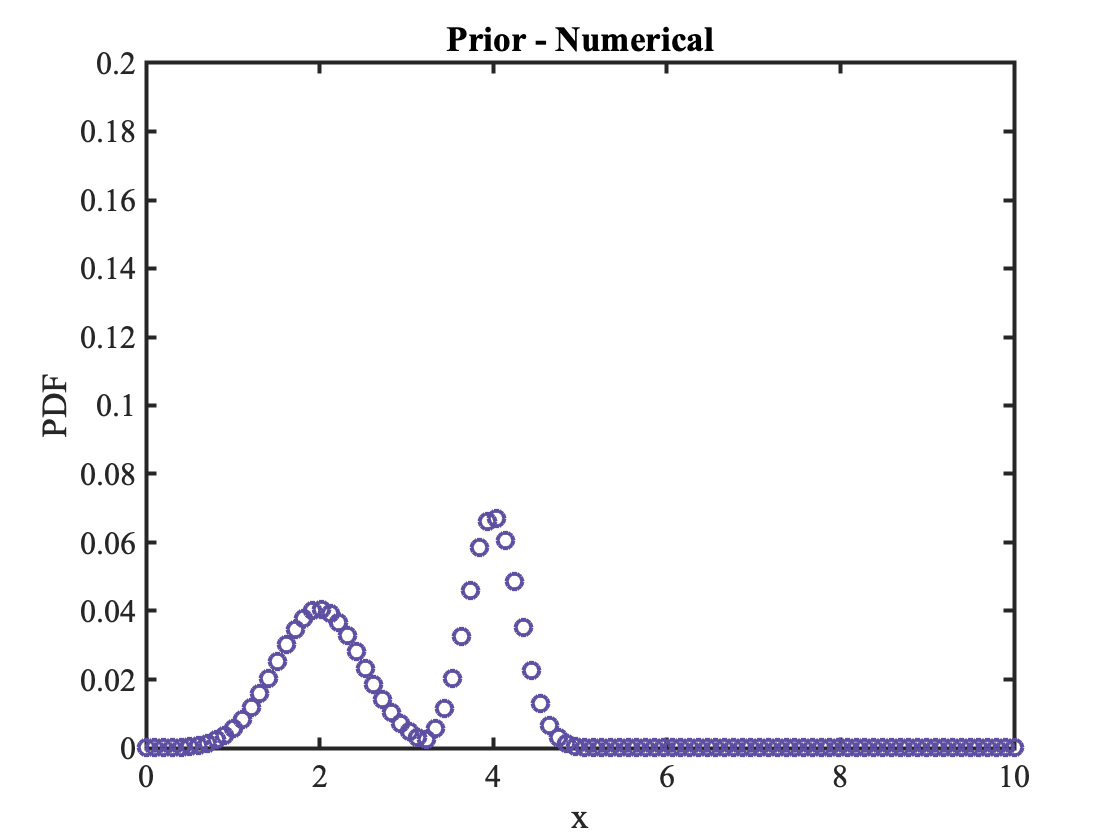

x = linspace(0,10,100);

mode1 = normpdf(x, 2, 0.5);
mode2 = normpdf(x, 4, 0.3);

prior = mode1;
prior(mode2 > mode1) = mode2(mode2 > mode1);
prior = prior / sum(prior); % normalize 

figure();
plot(x, prior, 'o', 'markersize', 8);
ylim([0, 0.2]);
xlabel('x');
ylabel('PDF');
title('Prior - Numerical');

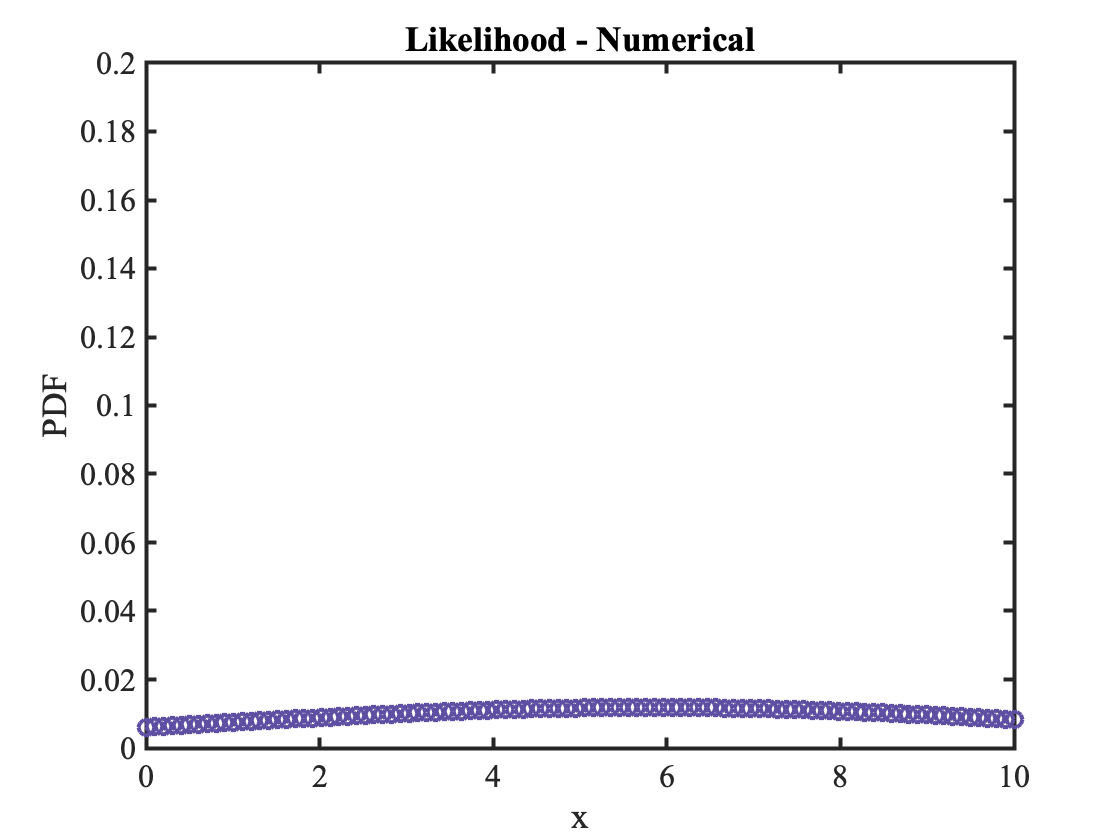


likelihood = normpdf(x, 5.8, 5);
likelihood = likelihood / sum(likelihood); % normalize 

figure();
plot(x, likelihood, 'o', 'markersize', 8);
ylim([0, 0.2]);
xlabel('x');
ylabel('PDF');
title('Likelihood - Numerical');

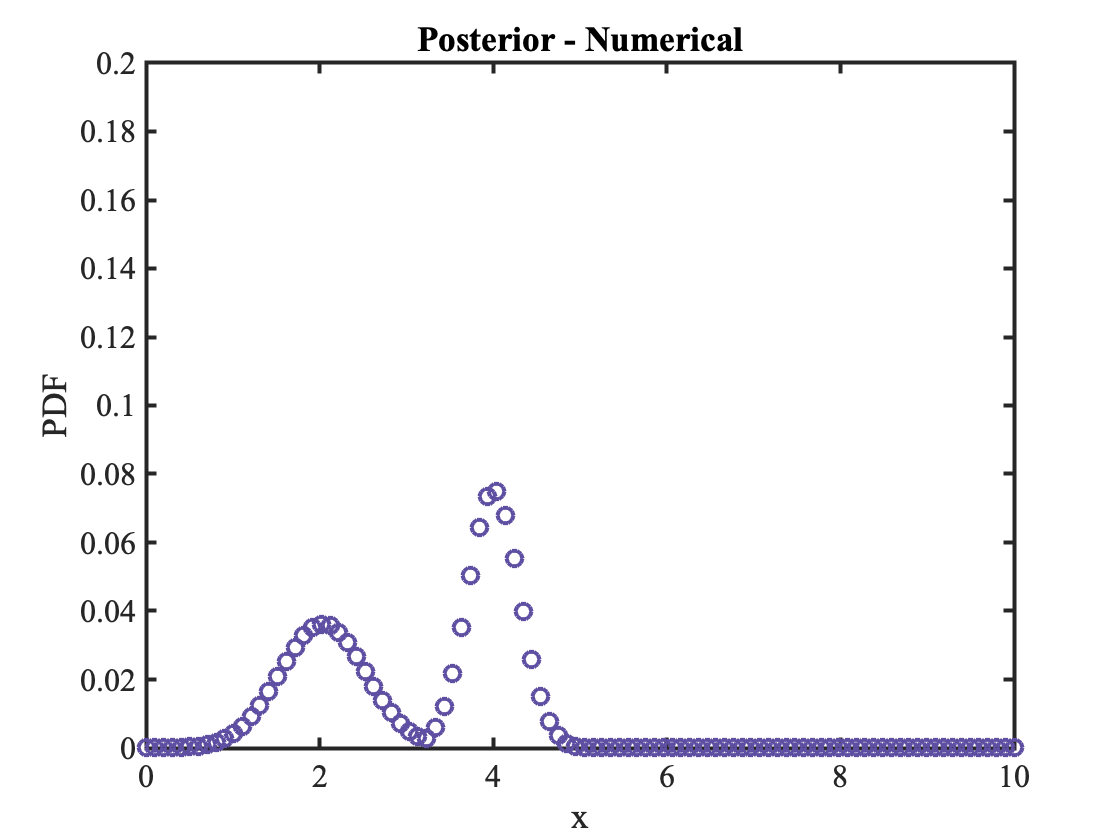


posterior = prior .* likelihood;
posterior = posterior / sum(posterior); % normalize 

figure();
plot(x, posterior, 'o', 'markersize', 8);
ylim([0, 0.2]);
xlabel('x');
ylabel('PDF');
title('Posterior - Numerical');